% importing the 3 images 
im_locs = ["/home/aaron/Projects/classWork/CMPSC497/week_4/center.png";
"/home/aaron/Projects/classWork/CMPSC497/week_4/left.png" ;
"/home/aaron/Projects/classWork/CMPSC497/week_4/right.png"]

im_locs = 3×1 string array
    "/home/aaron/Projects/classWork/CMPSC497/week_4/center.png"
    "/home/aaron/Projects/classWork/CMPSC497/week_4/left.png"
    "/home/aaron/Projects/classWork/CMPSC497/week_4/right.png"


im = 210×327×3 uint8 array
im(:,:,1) =

   104   120   108   132   139   137   131   141   141   139   140   138   136   136   138   148   146   142   141   142   142   141   143   144   144   143   144   144   146   151   147   150   151   151   149   150   154   156   156   152   146   152   144   150   152   149   148   149   133   121   163   167   150   150   136   119   166   159   153   142   156   158   156   122   109   130   143   150   147   141   149   152   153   153   149   151   151   129   140   150   140   143    86    84    23    16    14    16    44   114   157   156   149   158   137   145   152   132   115   144   143   126    99    95   108   136   134   129   130   149   151   152   151   152   154   148   141   132   125   126   128   141   137   139   146   147   150   135   147   134   139   133   124   124   126   154   157   154   156   155   148   122   136   154   127   134   153   143   153   155   142   117   129   155   150   123   129   152   152   158

im_partitions = 1×1 cell array
    {0×0 double}


pixel_sums_per_partition = 0

kernel =     -1     2    -1
    -1     2    -1
    -1     2    -1


height = 210

width = 327

partition_width = 327

partition_start = 1

partition_end = 327

im_partitions = 1×1 cell array
    {210×327 logical}


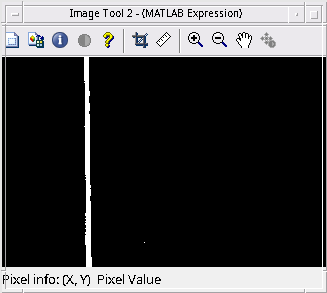


% testing images from lecture slides 
im = im_locs{2};
num_partitions = 1;
commands = {'Straight', 'Right', 'Left'};
move = generateCommand(im, num_partitions, commands);


disp(move)

Straight



% im_center = imread(im_locs(1));
% im_left = imread(im_locs(2)); 
% im_right = imread(im_locs(3));
% 
% % min width from workspace section observation 
% min_width = 327; 
% 
% % scaling down all image uniformaly
% im_center = im_center(:,1:min_width,:)
% im_left = im_left(:,1:min_width,:) 
% im_right = im_right(:,1:min_width,:);
% 
% % making gray and binarizing 
% gp = 0.20 % low gray point leads to ideal scenario -> high contrast
% 
% im_center = imbinarize(rgb2gray(im_center), gp);
% im_left = imbinarize(rgb2gray(im_left), gp); 
% im_right= imbinarize(rgb2gray(im_right), gp);
% 
% % applying color inversion to make everything but the line black
% im_center = ~im_center;
% im_left = ~im_left;
% im_right = ~im_right;
% 
% % creating a vertical line mask 
% kernel = [-1 2 -1; -1 2 -1; -1 2 -1]
% 
% % testing filter 
% g = imfilter(im_right, kernel)
% imtool(g)
% 
% 
% g = imfilter(im_center, kernel)
% imtool(g)
% 
% 
% g = imfilter(im_left, kernel)
% imtool(g)



% function to generate movement command - given an image - the function
% divides the image into n-partitions and maps each one to a value in
% the commands list. By applying a mask over each section and selecting
% the section with the highest pixel sum, we return the command that
% corresponds to selecting a given partition
% size(commands) == size(num_partitions)

function [movement_command] = generateCommand(im_loc, num_partitions, commands) 
    % preprocessing
    im = imread(im_loc)

    % smoothing histogram of image...possibly

    % binarizing 
    im = imbinarize(rgb2gray(im), .2);

    % inverting 
    im = ~im;

    % allocate space
    im_partitions = cell(1, num_partitions)
    pixel_sums_per_partition = zeros(1, num_partitions)
    kernel = [-1 2 -1; -1 2 -1; -1 2 -1]
    
    % make the height and width uniform 
    [height, width] = size(im)

    % partition equally 
    partition_width = floor(width / num_partitions)

    

    for i = 1:num_partitions
        partition_start = (i-1) * partition_width + 1
        partition_end = i * partition_width

        % add remaining columns in we reach the last partition 
        if i == num_partitions
            partition_end = width;
        end 

        % save each partition to arrary
        im_partitions{i} = im(:,partition_start:partition_end)
        imtool(im_partitions{i})

        % summing pixel vals in partition 
        filtered_partition = imfilter(im_partitions{i}, kernel);
        pixel_sums_per_partition(i) = sum(filtered_partition(:)); 
    end

    % getting index of greatest pixel sum
    [~, max_par_index] = max(pixel_sums_per_partition); % ~ -> place holder...we dont care about the actual value just the index

    % return the movement command thats mapped to this partition
    movement_command = commands{max_par_index};

end 









